# Visualizing of Data

## Head

clear 
clc
close all 
warning('off','all')
[pathstr,~,~] = fileparts(mfilename('fullpath'));
cd(pathstr)
format longG

## Import

 
[filename, pathToLog] = uigetfile('*.csv');
filename

filename = '202206301141_Log.csv'

if pathToLog == 0
    return
end
[savePath, ~, ~] = fileparts(pathToLog);
Csv = readtable(strcat(pathToLog, "\", filename));
Dataset = Csv;
if width(Csv) < 22
    ChannelNumber = 2;
else
    ChannelNumber = 4;
end
if ChannelNumber == 4
    Channels = ["A", "B", "C", "D"];
else
    Channels = ["A", "B"];
end

## Correcting Offset

NumberOffsetvalues = 2;
for i = 7:7+ChannelNumber-1
    [MinValues, Index] = sort(Csv.(i));
    Min = MinValues(NumberOffsetvalues);    
    Dataset.(i) = Csv.(i) - Min;
    if NumberOffsetvalues > 1
        for j = 1:NumberOffsetvalues -1
            IndexToCorrect = Index(j);
            Dataset.(i)(IndexToCorrect) = Dataset.(i)(IndexToCorrect) - (MinValues(j) - Min);
        end
    end
end
if ChannelNumber == 4    
    for i = 15:15+ChannelNumber-1
        [MinValues, Index] = sort(Csv.(i));
        Min = MinValues(NumberOffsetvalues);  
        Dataset.(i) = Csv.(i) - Min;
        Dataset.(i+ChannelNumber) = Csv.(i+ChannelNumber) - Min;
        if NumberOffsetvalues > 1
            for j = 1:NumberOffsetvalues -1
                IndexToCorrect = Index(j);
                Dataset.(i)(IndexToCorrect) = Dataset.(i)(IndexToCorrect) - (MinValues(j) - Min);
                Dataset.(i+ChannelNumber) = Dataset.(i+ChannelNumber)- (MinValues(j) - Min);
            end
        end
    end
else
    for i = 11:11+ChannelNumber-1
        [MinValues, Index] = sort(Csv.(i));
        Min = MinValues(NumberOffsetvalues);    
        Dataset.(i) = Csv.(i) - Min;
        Dataset.(i+ChannelNumber) = Csv.(i+ChannelNumber) - Min;
        if NumberOffsetvalues > 1
            for j = 1:NumberOffsetvalues -1
                IndexToCorrect = Index(j);
                Dataset.(i)(IndexToCorrect) = Dataset.(i)(IndexToCorrect) - (MinValues(j) - Min);
                Dataset.(i+ChannelNumber) = Dataset.(i+ChannelNumber)- (MinValues(j) - Min);
            end
        end
    end
end

if ChannelNumber == 4
    v_vector = [Dataset.MeansA, Dataset.MeansB, Dataset.MeansC, Dataset.MeansD];
else 
    v_vector = [Dataset.MeansA, Dataset.MeansB];
end
sz = [ChannelNumber 5];
columns = ["Channel", "Means in mV", "Std in mV", "Min in mV", "Max in mV"];
varTypes = ["string", "double", "double", "double", "double"];
Characteristics = table('Size', sz, 'VariableTypes', varTypes, 'VariableNames', columns);
for i = 1:ChannelNumber
    [~, j] = max(v_vector(:, i));
    if ChannelNumber == 4
        Characteristics(i, :) = {Channels(i), round(table2array(Dataset(j, 7 + i - 1)), 1),  round(table2array(Dataset(j, 11 + i - 1)), 1), round(table2array(Dataset(j, 15 + i - 1)), 1), round(table2array(Dataset(j, 19 + i - 1)), 1)};
    else
        Characteristics(i, :) = {Channels(i), round(table2array(Dataset(j, 7 + i - 1)), 1),  round(table2array(Dataset(j, 9 + i - 1)), 1), round(table2array(Dataset(j, 11 + i - 1)), 1), round(table2array(Dataset(j, 13 + i - 1)), 1)};
    end
end
Characteristics

Characteristics = 2×5 table
    Channel    Means in mV    Std in mV    Min in mV    Max in mV
    _______    ___________    _________    _________    _________

      "A"         16.3          61.1            0         582.7  
      "B"         24.9          86.7         15.7         724.4  


## Plot 3D Figure

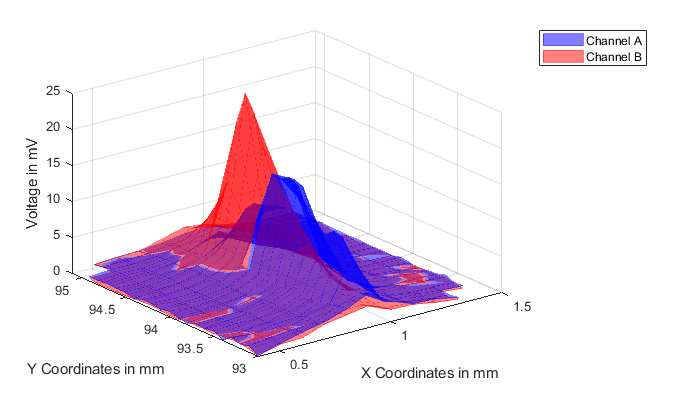


f1 = figure('Name', 'Means A, B, C, D');
x = Csv.XCoordinatesInMm;
y = Csv.YCoordinatesInMm;
v = v_vector(:, 1);
[xq,yq] = meshgrid(min(x):.1:max(x), min(y):.1:max(y));
AlphaA = 0.5;
vq = griddata(x,y,v, xq, yq, 'cubic');
mesh(xq, yq, vq, 'FaceColor', 'b', 'EdgeColor', 'b', 'DisplayName','Channel A', 'FaceAlpha', AlphaA, 'EdgeAlpha', AlphaA)
hold on

v = v_vector(:, 2);
vq = griddata(x,y,v, xq, yq, 'cubic');
AlphaB = 0.5;
mesh(xq, yq, vq, 'FaceColor', 'r', 'EdgeColor', 'r', 'DisplayName','Channel B', 'FaceAlpha', AlphaB, 'EdgeAlpha', AlphaB)
hold on

if ChannelNumber == 4
    v = v_vector(:, 3);
    vq = griddata(x,y,v, xq, yq, 'cubic');
    AlphaC = 0.5;
    mesh(xq, yq, vq, 'FaceColor', '#77AC30', 'EdgeColor', '#77AC30', 'DisplayName','Channel C', 'FaceAlpha', AlphaC, 'EdgeAlpha', AlphaC)
    hold on
    
    v = v_vector(:, 4);
    vq = griddata(x,y,v, xq, yq, 'cubic');
    AlphaD = 0.5;
    mesh(xq, yq, vq, 'FaceColor', '#EDB120', 'EdgeColor', '#EDB120', 'DisplayName','Channel D', 'FaceAlpha', AlphaD, 'EdgeAlpha', AlphaD)
end
xlabel('X Coordinates in mm');
ylabel('Y Coordinates in mm');
zlabel('Voltage in mV');
f1.Position = [10 10 700 400];
legend;

%saveas(f1, strcat(savePath, "\", "3D-Plot.jpg")); 


 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for i = 1:ChannelNumber
    Max = max(v_vector(:, i));
    v_vector_normalized(:, i) = v_vector(:, i)/ Max;
end

## Plot Contour

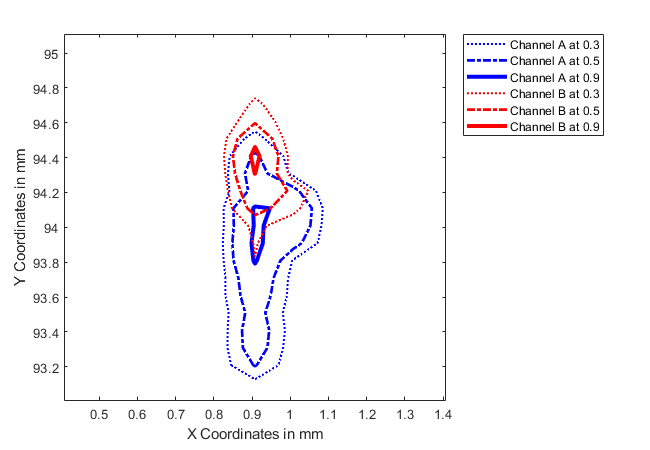

f2 = figure('Name', 'Hoehenlinie');
x = Csv.XCoordinatesInMm;
y = Csv.YCoordinatesInMm;
FirstThreshold =0.3;
SecondThreshold = 0.5;
ThirdThreshold = 0.9;
k0=[FirstThreshold,FirstThreshold];
k1=[SecondThreshold,SecondThreshold];
k2=[ThirdThreshold,ThirdThreshold];
k = [k0; k1; k2];
Width = [1.5, 2, 3];
Colors = ["b", "r", "g", "y"];
Style = [":", "-.", ""];

for i = 1:size(v_vector_normalized, 2)
    v = v_vector_normalized(:, i);
    vq = griddata(x,y,v, xq, yq, 'cubic');
    for j = 1:3
        [M,c] = contour(xq, yq, vq, k(j,:), strcat(Style(j), Colors(i)), 'DisplayName',strcat("Channel ", Channels(i), " at " , num2str(max(k(j,:)))));
        c.LineWidth = Width(j);
        hold on
    end
end
legend('location', 'northeastoutside')
xlabel('X Coordinates in mm');
ylabel('Y Coordinates in mm');

f2.Position = [10 10 650 450];
hold off

%saveas(f2, strcat(savePath, "\", "Contour-Plot.jpg")); 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%